# Parameter Regression with Arduino Data

The objective of this activity is to fit empirical and physics-based predictions to the data for a two heater model of the temperature control lab. Select parameters are adjusted to minimize the sum of squared errors (SSE) or the integral absolute error (IAE) between the model predicted values and the measured values.


$$IAE_{model} = \sum_{i=0}^n \left| T_{1,meas,i} - T_{1,pred,i} \right| + \left| T_{2,meas,i} - T_{2,pred,i} \right|$$


Use an optimizer to adjust the parameters and achieve alignment between the model and the measured values.

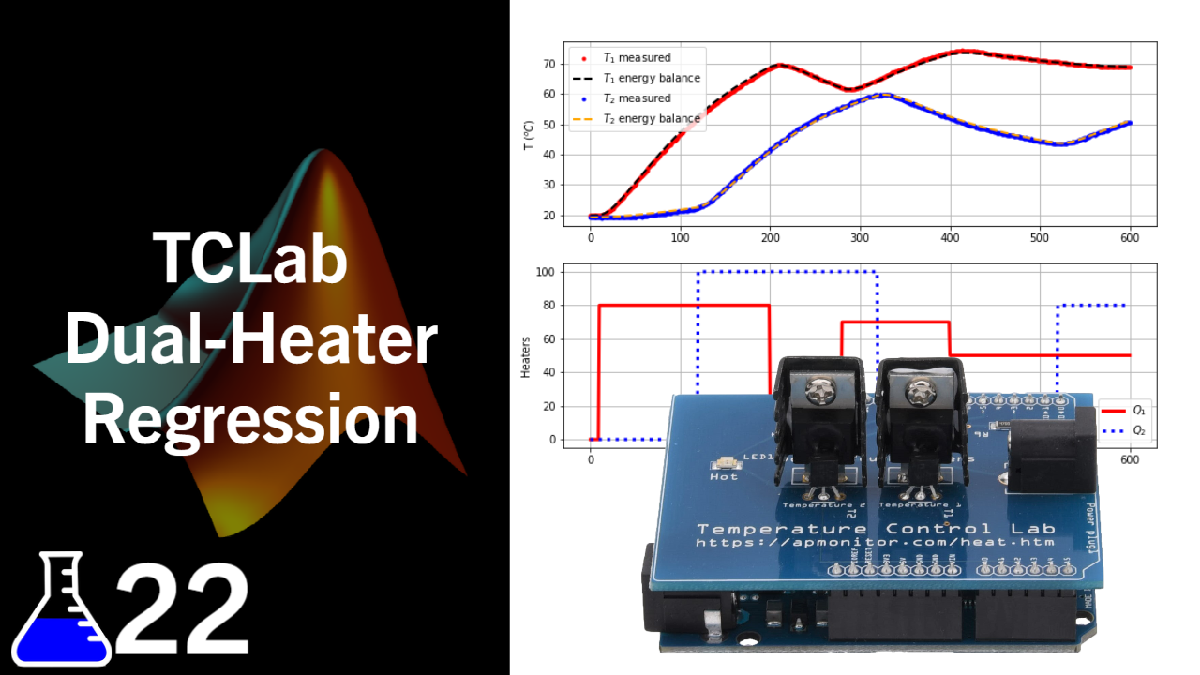

### [View Lecture](https://youtu.be/HisCnxGo4kg)

## Step Test for Parameter Regression

clc; clear all; close all;
tmp = matlab.desktop.editor.getActive;
directory = fileparts(tmp.Filename);

% Collect data
filename = "twoHeaterResponse.csv";
absolute_path = fullfile(directory, filename);

try % try to read from file first
    A = readmatrix(absolute_path)
    tm_ = A(:,1);
    T1_ = A(:,2);
    T2_ = A(:,3);
    Q1_ = A(:,4);
    Q2_ = A(:,5);
    disp('TCLab Data read from file')
    
    figure()
    hold on
    subplot(2,1,1)
    plot(tm_, T1_, 'r.', 'DisplayName','T1')
    hold on
    plot(tm_, T2_, 'b.', 'DisplayName','T2')
    hold off
    legend('Location',"best")
    ylabel('Temperature (C)')
    subplot(2,1,2)
    plot(tm_, Q1_, 'r-','DisplayName','Q1')
    hold on
    plot(tm_, Q2_, 'b-','DisplayName','Q2')
    hold off
    xlabel('Time (sec)')
    ylabel('Heater Setting (%)')
    legend('Location',"best")
    
catch % if file can not be found, simulate
    try 
        n = 15*60;
        % Create Arrays
        T1_ = ones(n+1, 1);
        T2_ = ones(n+1, 1);
        tm_ = zeros(n+1, 1);
        Q1_ = zeros(n+1, 1);
        Q2_ = zeros(n+1, 1);
        % Adjust Heater Steps
        Q1_(10:240) = 70;
        Q2_(240:480) = 100;
        Q1_(400:600) = 90;
        Q1_(600:750) = 30;
        Q2_(600:800) = 40;

        % initialize lab        
        lab = tclab;
        T1_ = T1_ * lab.T1;
        T2_ = T2_ * lab.T1;
        tic;
        figure()
        hold on
        for i=2:n+1
            pause(1-mod(toc,1));
            tm_(i) = toc;
            T1_(i) = lab.T1;
            T2_(i) = lab.T2;  
            lab.Q1(Q1_(i));
            lab.Q2(Q2_(i));
            
            subplot(2,1,1)
            plot(tm_(1:i), T1_(1:i), 'r.',tm_(1:i), T2_(1:i), 'b.')
            legend({'T1' 'T2'}, 'Location',"best")
            ylabel('Temperature (C)')
            subplot(2,1,2)
            plot(tm_(1:i), Q1_(1:i), 'r-',tm_(1:i), Q2_(1:i), 'b-')
            xlabel('Time (sec)')
            ylabel('Heater Setting (%)')
            legend({'Q1' 'Q2'}, 'Location',"best")
            
        end
        lab.off;
        clear lab;
        
        % save
        A = [tm_, T1_, T2_, Q1_, Q2_]
        writematrix(A, absolute_path, 'Delimiter', ',')
        
    catch % if an error, turn off heater and close
        lab.off;
        clear lab;
    end
    
end

## Graphical FOPDT Fit

Adjust the sliders below to adjust the FOPDT parameters and estimate a graphical fit to the data. The FOPDT equation includes disturbance gain 

Kp =   0.65;
Kd =   0.1;
taup =  120;
thetap = 16;
fopdtPlot(tm_, T1_, T2_, Q1_, Q2_, Kp, Kd, taup, thetap)

### Optimized FOPDT Fit

Use minimization functions such as `fminsearch` or `fmincon` to regress FOPDT Parameters for the system with the step test already performed.

## Test Dual Heater Physics-based Model with Optimization

Starting with the dual heater energy balances, adjust parameters such as $U$ the heat transfer coefficient, $\alpha_1$ or $\alpha_2$ the heater power factors, or other uncertain parameters that will improve the fit to the data. Other factors such as the ambient temperature ($T_\infty$), can be updated by noting the temperature when the device is cool and the heaters are initially off.

## Fit Second-Order Physics-based Model with Optimization

A second-order physics-based model starts with the dual heater energy balances but adds additional equations for the conduction of heat from the heater to the temperature sensor. The heat loss by convection and conduction from the thermistor sensor is assumed to be negligible and the principal heat transfer is by conduction. The temperatures of the heaters $T_{H1}$ and $T_{H2}$ are related to the temperatures of the sensors $T_{C1}$ and $T_{C2}$ with a discretized version of Fourier's law with thermal conductivity ($k$), cross-section area for conduction ($A$), and distance between the heater and sensor $\Delta x$.


$$m \, c_p \, \frac{dT_{C1}}{dt} = \frac{k\,A_c}{\Delta x} \left( T_{H1} - T_{C1} \right)$$



$$m \, c_p \, \frac{dT_{C2}}{dt} = \frac{k\,A_c}{\Delta x} \left( T_{H2} - T_{C2} \right)$$


The time constant form of the conduction equation is obtained by defining $\tau$ for all the parameters that are lumped into a single constant.


$$\tau = \frac{m \, c_p \, \Delta x}{k\,A_c}$$


The new equation is a standard first order linear system that relates the heater actuator temperature to the sensor where the temperature is physically measured.


$$\tau \frac{dT_{C1}}{dt} = T_{H1} - T_{C1}$$



$$\tau \frac{dT_{C2}}{dt} = T_{H2} - T_{C2}$$


In this regression, parameters $U$, $U_s$, $\alpha_1$, $\alpha_2$, and $\tau$ are adjusted to minimize the model error objective function. The additional $U_s$ is the modified heat transfer coefficient between the heaters that is higher than the heat transfer coefficient from natural convection.

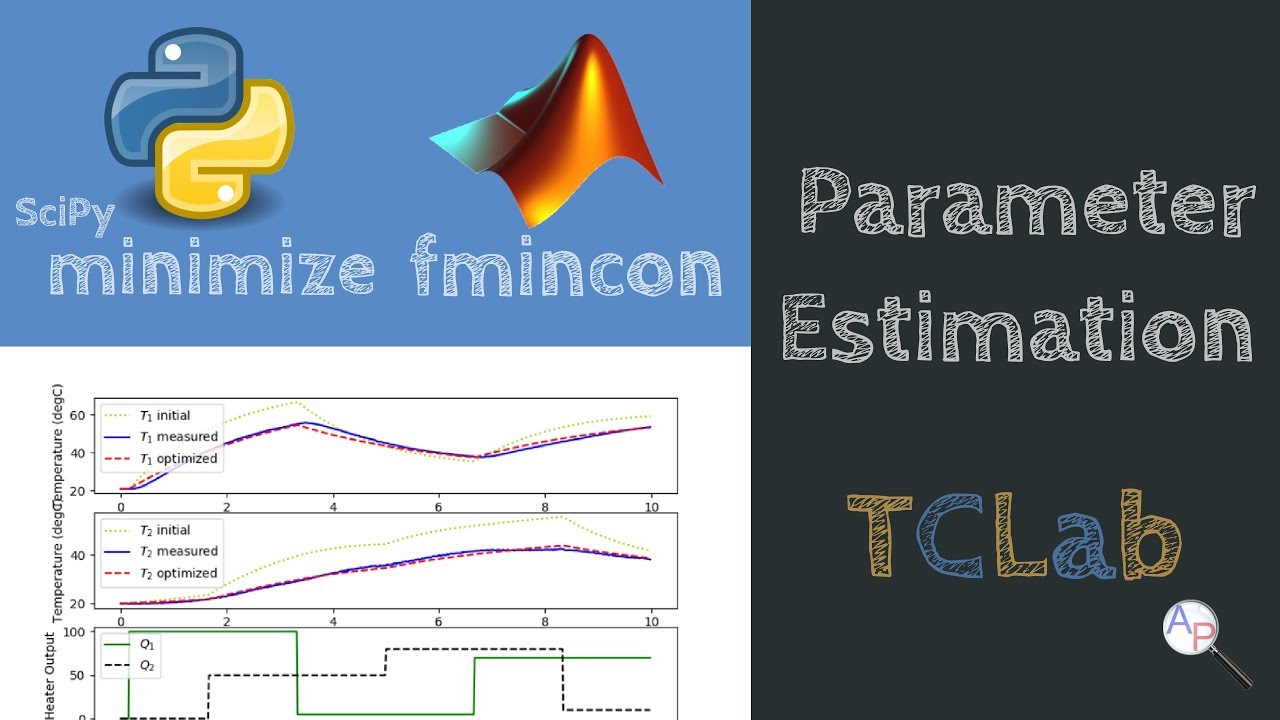

### [View Lecture](https://www.youtube.com/watch?v=SwogAa1719M)

function dYdt = process(~, Y, u1, u2, Kp, Kd, taup, y0)
    y1 = Y(1);
    y2 = Y(2);
    
    dy1dt = (1.0/taup) * (-(y1-y0) + Kp * u1 + Kd * (y2-y1));
    dy2dt = (1.0/taup) * (-(y2-y0) + (Kp/2.0) * u2 + Kd * (y1-y2));
    
    dYdt = [dy1dt; dy2dt];
end

function fopdtPlot(tm_, T1_, T2_, Q1_, Q2_, Kp, Kd, taup, thetap)
    y0 = T1_(1);
    n = length(tm_);
    
    T1_fopdt = ones(n, 1) * y0;
    T2_fopdt = ones(n, 1) * y0;
    T0 = [y0;y0];
    
    for i=1:n-1
        ts = [tm_(i), tm_(i+1)];
        u1 = Q1_(max(1,i-round(thetap)));
        u2 = Q2_(max(1,i-round(thetap)));
        [~, T] = ode45(@(t,y)process(t,y,u1,u2,Kp,Kd,taup,y0), ts, T0);
        T0 = T(end,:);
        T1_fopdt(i+1) = T0(1);
        T2_fopdt(i+1) = T0(2);
    end
    
    iae = sum((T1_-T1_fopdt).^2) + sum((T2_-T2_fopdt).^2);
    disp(iae)
    figure()
    subplot(2,1,1)
    plot(tm_, T1_, 'r.', 'DisplayName','TCLab T1')
    hold on
    plot(tm_, T2_, 'b.', 'DisplayName','TCLab T2')
    hold on
    plot(tm_, T1_fopdt, 'r--', 'DisplayName','FOPDT T1')
    hold on
    plot(tm_, T2_fopdt, 'b--', 'DisplayName','FOPDT T1')
    hold off
    ylabel('Temperature ($^\circ$C)', 'Interpreter',"latex")
    legend('Location',"best")
    text(200, 23, 'IAE:'+string(round(iae)))
    subplot(2,1,2)
    plot(tm_, Q1_, 'r-', 'DisplayName','TCLab Q1')
    hold on
    plot(tm_, Q2_, 'b-', 'DisplayName','TCLab Q2')
    hold off
    ylabel('Heater Setting (%)')
    legend('Location',"best")
    xlabel('Time(s)')
end

function T = sim_process(params, tm_, T1_, T2_, Q1_, Q2_)
    Kp = params(1);
    Kd = params(2);
    taup = params(3);
    thetap = params(4);

    y0 = T1_(1);
    
    n = length(tm_);
    
    T1_fopdt = ones(n, 1) * y0;
    T2_fopdt = ones(n, 1) * y0;
    T0 = [y0;y0];
    
    for i=1:n-1
        ts = [tm_(i), tm_(i+1)];
        u1 = Q1_(max(1,i-round(thetap)));
        u2 = Q2_(max(1,i-round(thetap)));
        [~, T] = ode45(@(t,y)process(t,y,u1,u2,Kp,Kd,taup,y0), ts, T0);
        T0 = T(end,:);
        T1_fopdt(i+1) = T0(1);
        T2_fopdt(i+1) = T0(2);
    end
    T = [T1_fopdt, T2_fopdt];
end

function sse = objective_fopdt(params, tm_, T1_, T2_, Q1_, Q2_)
    T = sim_process(params, tm_, T1_, T2_, Q1_, Q2_);
    T1p = T(1);
    T2p = T(2);
    sse = sum((T1_ - T1p).^2) + sum((T2_ - T2p).^2);
end

function dTdt = heat(~,x,Q1,Q2,p)
    %U = 10.0;           % W/m^2-K
    %alpha1 = 0.0100;    % W / % heater 1
    %alpha2 = 0.0075;    % W / % heater 2
    U = p(1);
    alpha1 = p(2);
    alpha2 = p(3);

    % Parameters
    Ta = 23 + 273.15;   % K
    m = 4.0/1000.0;     % kg
    Cp = 0.5 * 1000.0;  % J/kg-K    
    A = 10.0 / 100.0^2; % Area in m^2
    As = 2.0 / 100.0^2; % Area in m^2
    eps = 0.9;          % Emissivity
    sigma = 5.67e-8;    % Stefan-Boltzman

    % Temperature States
    T1 = x(1)+273.15;
    T2 = x(2)+273.15;

    % Heat Transfer Exchange Between 1 and 2
    conv12 = U*As*(T2-T1);
    rad12  = eps*sigma*As * (T2^4 - T1^4);

    % Nonlinear Energy Balances
    dT1dt = (1.0/(m*Cp))*(U*A*(Ta-T1) ...
            + eps * sigma * A * (Ta^4 - T1^4) ...
            + conv12 + rad12 ...
            + alpha1*Q1);
    dT2dt = (1.0/(m*Cp))*(U*A*(Ta-T2) ...
            + eps * sigma * A * (Ta^4 - T2^4) ...
            - conv12 - rad12 ...
            + alpha2*Q2);
    dTdt = [dT1dt,dT2dt]';
end

function T = simulate(p, t, T1meas, T2meas, Q1, Q2)
T = zeros(length(t),2);
T(1,1) = T1meas(1);
T(1,2) = T2meas(1);
T0 = [T(1,1),T(1,2)];
for i = 1:length(t)-1
    ts = [t(i),t(i+1)];
    sol = ode15s(@(t,x)heat(t,x,Q1(i),Q2(i),p),ts,T0);
    T0 = [sol.y(1,end),sol.y(2,end)];
    T(i+1,1) = T0(1);
    T(i+1,2) = T0(2);
end
end

function obj = objective(p, t, T1meas, T2meas, Q1, Q2)
    % simulate model
    Tp = simulate(p, t, T1meas, T2meas, Q1, Q2);
    % calculate objective
    obj =  sum(((Tp(:,1)-T1meas)./T1meas).^2) ...
         + sum(((Tp(:,2)-T2meas)./T2meas).^2);
end

function dTdt = model(~  ,T,  Q1, Q2, params)
    % unpack states
    TH1 = T(1);
    TH2 = T(2);
    TC1 = T(3);
    TC2 = T(4);
    
    % Unpack Regressed Constants
    U = params(1);
    Us = params(2);
    alpha1 = params(3);
    alpha2 = params(4);
    tau = params(5);
    
    % Constants
    Ta =20.0+273.15;                     % K
    mass = 4.0/1000.0;                   % kg
    Cp = 0.5*1000.0;                     % J/kg-K    
    A = 10.0/100.0^2;                    % Area not between heaters in m^2
    As = 2.0/100.0^2;                    % Area between heaters in m^2
    eps = 0.9;                           % Emissivity
    sigma = 5.67e-8;                     % Stefan-Boltzmann
    
    % Heater Temperatures in Kelvin
    T1 = TH1 + 273.15;
    T2 = TH2 + 273.15;
    
    % Heat transfer between two heaters
    Q_C12 = Us*As*(T2-T1);  % Convective
    Q_R12 = eps*sigma*As*(T2^4-T1^4);  % Radiative
    
    % Calculate derivative values
    TH1dt = (1.0/(mass*Cp))*(U*A*(Ta-T1) ...
                + eps * sigma * A * (Ta^4 - T1^4) ...
                + Q_C12 + Q_R12 ...
                + alpha1*Q1);
    TH2dt = (1.0/(mass*Cp))*(U*A*(Ta-T2) ...
                + eps * sigma * A * (Ta^4 - T2^4) ...
                - Q_C12 - Q_R12 ...
                + alpha2*Q2);
    TC1dt = (TH1 - TC1)/tau;
    TC2dt = (TH2 - TC2)/tau;
    
    dTdt = [TH1dt; TH2dt; TC1dt; TC2dt];
end

function T_ = simModel(T0, tm_, Q1_, Q2_, params)
    n = length(tm_);
    TH1sim_ = ones(n, 1) * T0(1);
    TH2sim_ = ones(n, 1) * T0(2);
    TC1sim_ = ones(n, 1) * T0(1);
    TC2sim_ = ones(n, 1) * T0(2);
    
    T0 = [TH1sim_(1); TH2sim_(1); TC1sim_(1); TC2sim_(1)];
    for i=1:n-1
        ts = [tm_(i) tm_(i+1)];
        [~,T] = ode45(@( t,T) model(t,T,  Q1_(i), Q2_(i), params), ts, T0);
        T0 = T(end,:);
        TH1sim_(i+1) = T0(1);
        TH2sim_(i+1) = T0(2);
        TC1sim_(i+1) = T0(3);
        TC2sim_(i+1) = T0(4);
    end
    T_ = [TH1sim_, TH2sim_];
end

function sse = obj(params, tm_, Q1_, Q2_, T1m_, T2m_)
    Tsim = simModel([T1m_(1), T2m_(1)], tm_, Q1_, Q2_, params);
    
    sse = sum((Tsim(:,1) - T1m_).^2) + sum((Tsim(:,2) - T2m_).^2);
end
